% ========================================================================== 
% ECE6950 Research - The University of Utah
% Subject: Developing a Matlab code to seperate each chemical response 
%       into a seperate data set and analyize noise of the chemicals' 
%       responses on the ChemAirU sensor.
% Nov 6th, 2024
% ========================================================================== 

close all;
clear;

T = readtable('chem-date.csv');


% ============ENTER THE DESIRED ZOOM-IN RANGE========================

% Zomm-in to analyze data according to a specific range of time

% Extract the row values where the "Time" column of the "T" table values
% are between the indicated range below

% Enter the time value for STARTing Range after the ".. >=" below (inclusive).
% Enter the the time value for ENDing Range after the ".. <=" below (inclusive).

% The time range data must be the 2nd column.

rowsNeeded = T{:,2} >= 0.036226843 & T{:,2} <= 0.041303165;


% T is the name of the original table from the ".csv" file.
% In the above code, T(:,2) represents the values in the second column 
% of the table. The logical expression T(:, 2) > x & T(:,2) < y 
% creates a logical index of rows where the second column values satisfy 
% the condition between x to y. Then, 'subsetData' stores the subset 
% of data that meets this criterion, including all columns.

% ===================ORIGINAL DATA TABLE ANALYSIS==============================

t = T{:,2}';  % "Time" column, column 2, reading from the table T.

t_len = length(t); % length of the time data



relay = T{:,3}; % Column 3, "relay" reading

s1_c=T{:,4}; % Corrected final values of the Sensor 1 (offset, WE&AE corrections are done).

s2_c=T{:,5}; % Corrected final values of the Sensor 2.

s3_c=T{:,6}; % Corrected final values of the Sensor 3.

s4_c=T{:,7}; % Corrected final values of the Sensor 4.

fprintf('\n');
fprintf('The length of the time data, t_len =');

The length of the time data, t_len =

disp(t_len);

        5089




s1_len = length(s1_c); % Length of the data
s2_len = length(s2_c);
s3_len = length(s3_c);
s4_len = length(s4_c); 

fprintf('\nThe length of the Sensor 1, Sensor 2, Sensor 3, Sensor 4 data reading, respectively =\n');


The length of the Sensor 1, Sensor 2, Sensor 3, Sensor 4 data reading, respectively =


X = sprintf('%d; %d; %d; %d.',s1_len,s2_len,s3_len,s4_len);
disp(X)

5089; 5089; 5089; 5089.


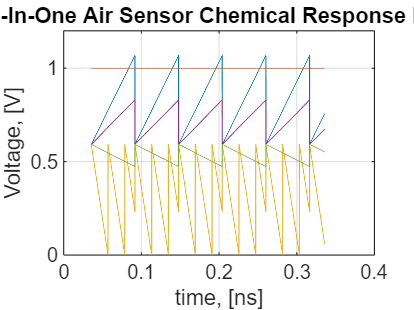



% The First Figure
figure('Name','All-In-One Sensor Data Plots'); % Figure#1
clf; % Clears the figures
plot(t,s1_c);
title('All-In-One Air Sensor Chemical Response Plots');grid on

xlabel('time, [ns]');
ylabel('Voltage, [V]');
hold on

plot(t,relay);
% xlim([inf 2]);
hold on
plot(t,s2_c);hold on
plot(t,s3_c);hold on
plot(t,s4_c);

hold off

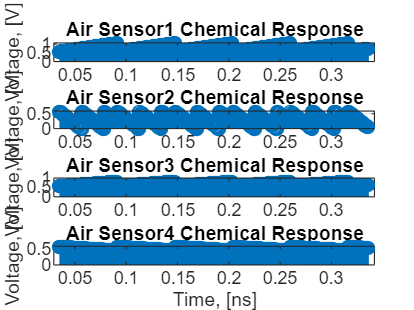



figure('Name','Individual Data In Subplots'); % Figure#2
clf; % Clears the figures

subplot(4,1,1); %
stem(t,s1_c);ylabel('Voltage, [V]');
% hold on;
% stem(t,relay);

title('Air Sensor1 Chemical Response');grid on
% ylim([-0.00025 0.003])

subplot(4,1,2); %
stem(t,s2_c);ylabel('Voltage, [V]');
title('Air Sensor2 Chemical Response');grid on
% ylim([-0.00025 0.003])

subplot(4,1,3); %
stem(t,s3_c);ylabel('Voltage, [V]');
title('Air Sensor3 Chemical Response');grid on
% ylim([-0.00025 0.003])

subplot(4,1,4); %
stem(t,s4_c);
title('Air Sensor4 Chemical Response');grid on
% ylim([-0.00025 0.003])

xlabel('Time, [ns]');
ylabel('Voltage, [V]');



%Sensor Reading Data Console Display

% fprintf('\nSensor 1, Sensor 2, Sensor 3, Sensor 4 Voltage Reading, respectively =\n');
% Y = sprintf('%f %f %f %f',s1_c',s2_c',s3_c',s4_c');
% disp(Y)

% fprintf('\n');
% fprintf('Sensor 1 Voltage Reading =');
% disp(s1_c);
% fprintf('Sensor 2 Voltage Reading =');
% disp(s2_c);
% fprintf('Sensor 3 Voltage Reading =');
% disp(s3_c);
% fprintf('Sensor 4 Voltage Reading =');
% disp(s4_c);

% ===================ZOOM-IN DATA TABLE ANALYSIS==============================
% Work here
% Copy column 1-3 for the zoomed data table
col1_3 = T(rowsNeeded, [1,2,3]);

zoom_in_data_table = [col1_3,  table(s1_c(rowsNeeded, :),s2_c(rowsNeeded, :),s3_c(rowsNeeded, :),s4_c(rowsNeeded, :))];
zoom_in_data_table = renamevars(zoom_in_data_table,["Var1","Var2","Var3","Var4"],["Sensor_1_zoom","Sensor_2_zoom","Sensor_3_zoom","Sensor_4_zoom"]);% rename the columnn #4-7

t_z = zoom_in_data_table{:,2}';  % "Time" column, the column 2, reading from the zoom in table

t_len_z = length(t_z); % length of the time data from the zoom-in data table

fprintf('\nZoom-In Table: Length of the time data, t_len_z =\n');


Zoom-In Table: Length of the time data, t_len_z =


disp(t_len_z);

    87




relay_z = zoom_in_data_table{:,3}; % Column 3, "relay" reading

s1_c_z = zoom_in_data_table{:,4}; % Column 4 reading. Corrected final values of the Sensor 1.
s1_len_z = length(s1_c_z); % Length of the data

s2_c_z = zoom_in_data_table{:,5}; % Column 5 reading. Corrected final values of the Sensor 2.
s2_len_z = length(s2_c_z);% Length of the data

s3_c_z = zoom_in_data_table{:,6}; % Column 6 reading. Corrected final values of the Sensor 3.
s3_len_z = length(s3_c_z);% Length of the data

s4_c_z = zoom_in_data_table{:,7}; % Column 7 reading. Corrected final values of the Sensor 4.
s4_len_z = length(s4_c_z);% Length of the data

fprintf('\nThe length of the Zoom-In Sensor 1, Sensor 2, Sensor 3, Sensor 4 data reading, respectively =\n');


The length of the Zoom-In Sensor 1, Sensor 2, Sensor 3, Sensor 4 data reading, respectively =


Z = sprintf('%d; %d; %d; %d.',s1_len_z,s2_len_z,s3_len_z,s4_len_z);
disp(Z)

87; 87; 87; 87.


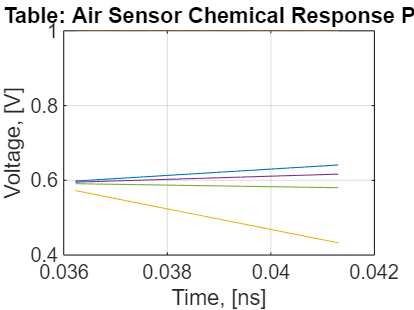


figure('Name','Zoom-In Table: All Sensor Data Plots');% Figure#3
% figure (3);
clf; % Clears the figures
plot(t_z,s1_c_z);
title('Zoom-In Table: Air Sensor Chemical Response Plot Results');grid on

xlabel('Time, [ns]');
ylabel('Voltage, [V]');
hold on

plot(t_z,relay_z); hold on
plot(t_z,s2_c_z);
plot(t_z,s3_c_z);
plot(t_z,s4_c_z);

hold off

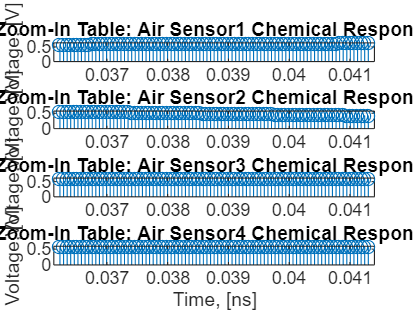



figure('Name','Zoom-In Table: Individual Data In Subplots');% Figure#4
clf; % Clears the figures

subplot(4,1,1); %
stem(t_z,s1_c_z);ylabel('Voltage, [V]');
title('Zoom-In Table: Air Sensor1 Chemical Response');grid on

subplot(4,1,2); %
stem(t_z,s2_c_z);ylabel('Voltage, [V]');
title('Zoom-In Table: Air Sensor2 Chemical Response');grid on

subplot(4,1,3); %
stem(t_z,s3_c_z);ylabel('Voltage, [V]');
title('Zoom-In Table: Air Sensor3 Chemical Response');grid on


subplot(4,1,4); %
stem(t_z,s4_c_z);
title('Zoom-In Table: Air Sensor4 Chemical Response');grid on

xlabel('Time, [ns]');
ylabel('Voltage, [V]');



% %Sensor Reading Data Console Display
% fprintf('\n');
% fprintf('Zoom-In Table: Sensor 1 Voltage Reading =');
% disp(s1_c_z);
% fprintf('Zoom-In Table: Sensor 2 Voltage Reading =');
% disp(s2_c_z);
% fprintf('Zoom-In Table: Sensor 3 Voltage Reading =');
% disp(s3_c_z);
% fprintf('Zoom-In Table: Sensor 4 Voltage Reading =');
% disp(s4_c_z);










